clear

DDynamic = readmatrix('surfdynamic.10k.txt');
DDynamic = sortrows(DDynamic(8:1279,1:10),1);
DDynamic = DDynamic(1:651,:);

[f,gof,out] = fit(DDynamic(:,1),DDynamic(:,10),'smoothingspline','SmoothingParam',0.7);
out.p

ans = 0.7000

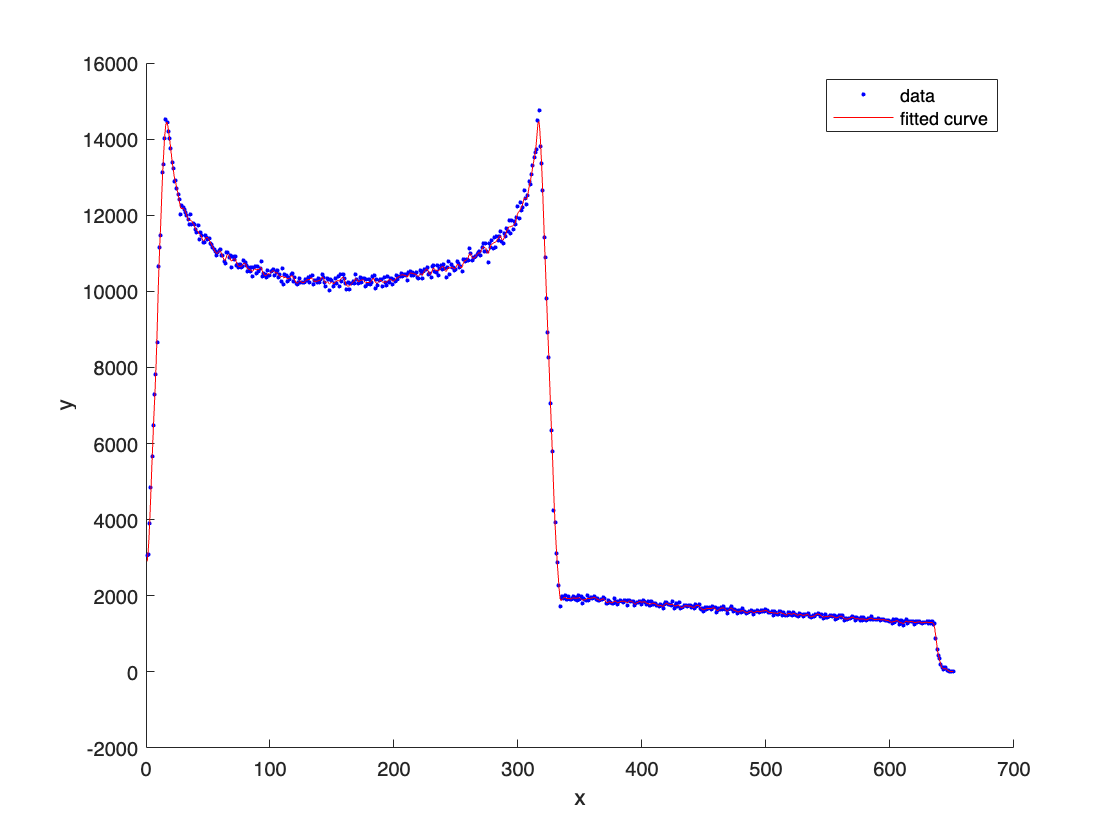


figure;
hold on
%plot(DDynamic(:,1),DDynamic(:,10))
plot(f,DDynamic(:,1),DDynamic(:,10))

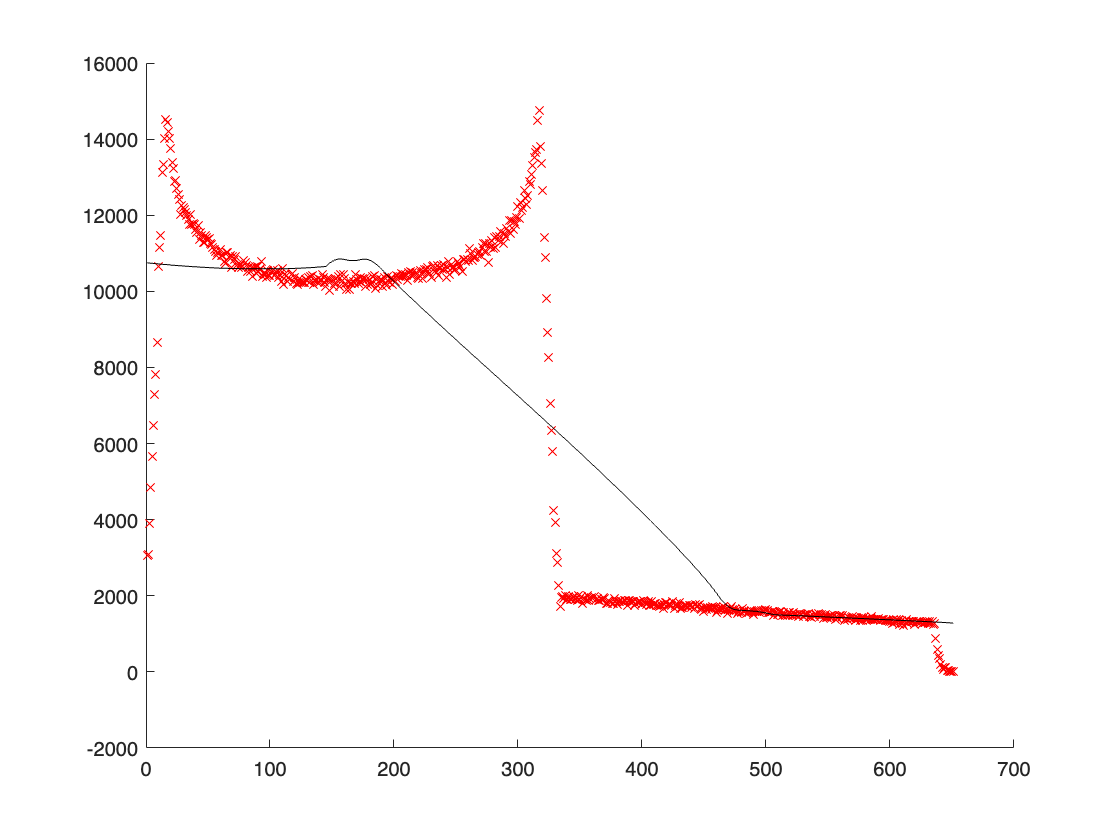


YS = smoothdata(DDynamic(:,10));
figure;
hold on
scatter(DDynamic(:,1),DDynamic(:,10),'x','r')
plot(DDynamic(:,1),YS,'k')